# Intro to Live Script

A Live Script is a matlab file which contains words and blocks of code which can be run one at a time. It's very similar to Jupyter Notebook. It's also similar to Mathematica. You can use it to tell a story with your code. 

# How to get started

Start a new live script by clicking on the New Live Script button on the HOME tab. Now click on the LIVE EDITOR tab. You can switch from text block or code block using the interface. The orange text is the title (Ctrl+alt+L) and this body is normal text (Ctrl+alt+t). You can switch to code text with (alt+enter). 

# Code

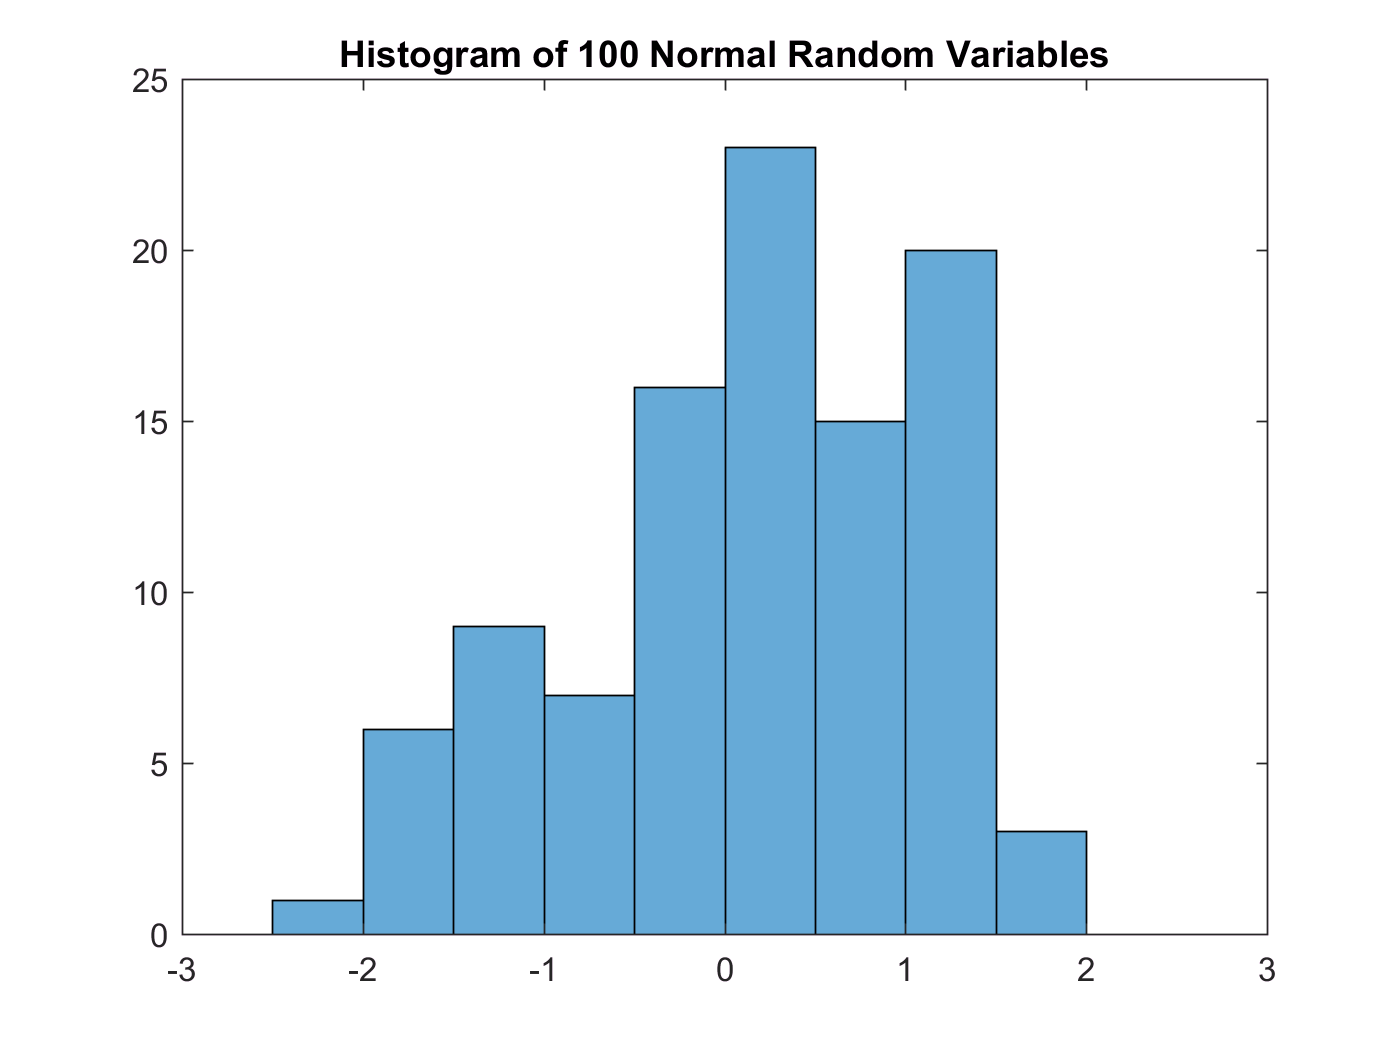

% this is a code block
% you can run blocks individually to help you debug your code 
u = randn(100,1); % generate an array of 100 normal random variables 
histogram(u)
title('Histogram of 100 Normal Random Variables')
xlim([-3 3])

# Sliders 

My favorite feature of the Live Script is the slider. Go to the INSERT tab and click on the Control and then add a Numeric Slider. You can assign a variable to the slider value. 

n =3317;

The slider is an interactive tool that lets you change the value of the variable n. 

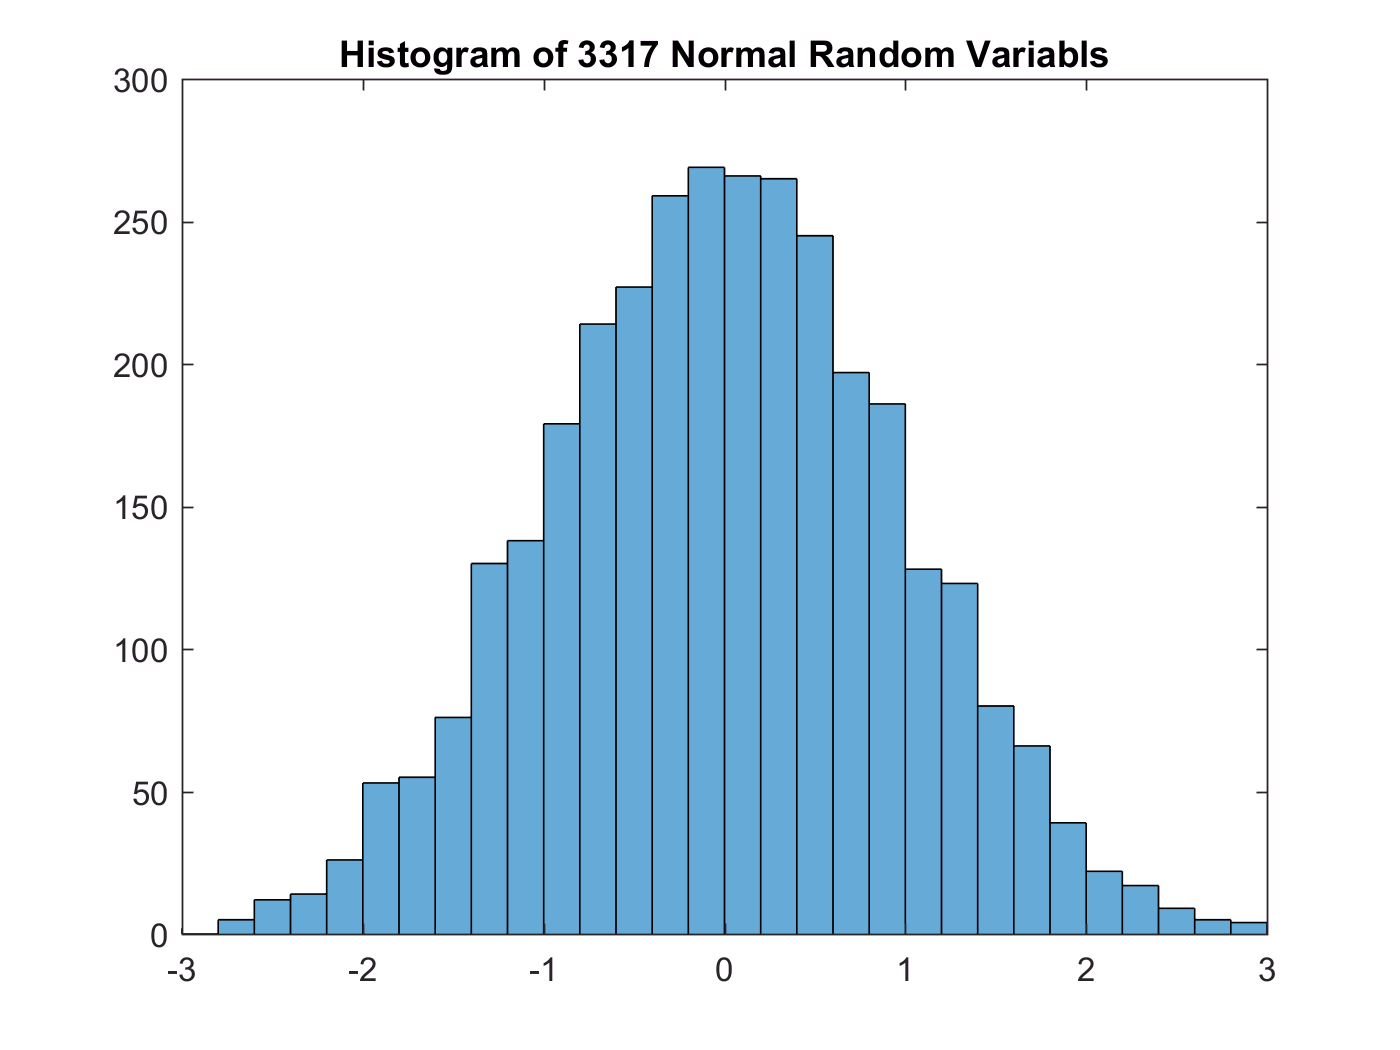

histogram(randn(n,1))
title(sprintf('Histogram of %d Normal Random Variabls',n))
xlim([-3 3])

The figure updates as you change adjust the slider. This is very useful if you want to see how a figure changes as you vary some parameter. The dropdown menu works in a similar way. 

# Plot Settings

The dropdown menu is another interactive tool. Play with the different plot settings. Below is a plot of 


$$y\left(x\right)=\frac{\mathrm{sin}\left(2\pi x\right)}{2\pi x}$$


You can use either Latex or 'Equation' to write out math equations.

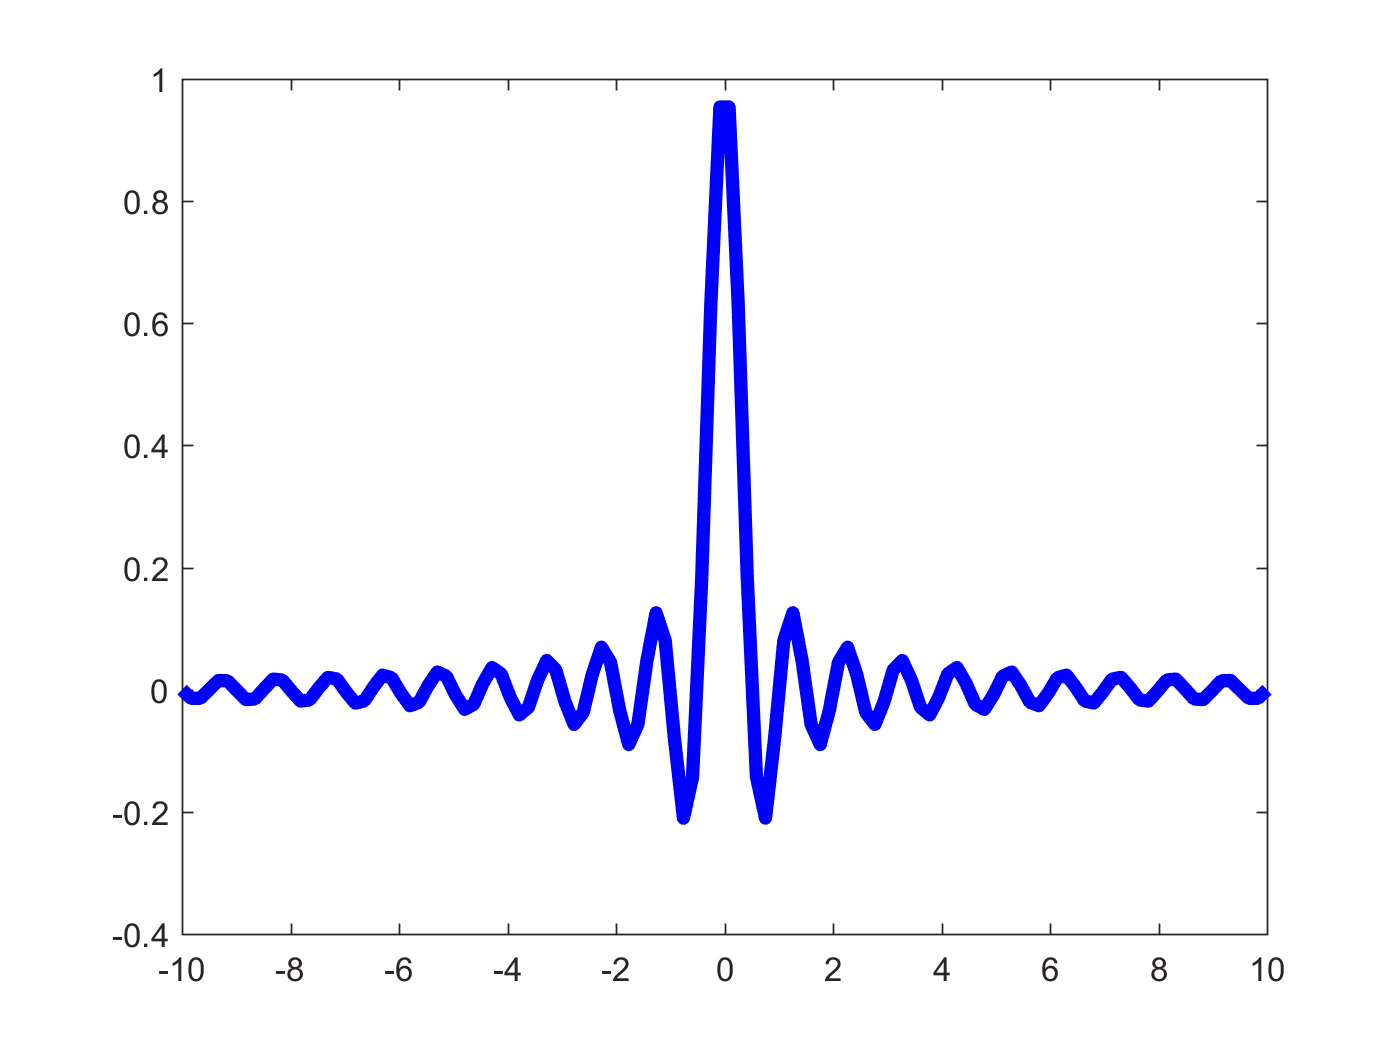

style = ['-', 'b'];
width = 4;
points =120;

x = linspace(-10,10,points);
y = sin(2*pi*x)./(2*pi*x);
plot(x,y,style,'linewidth',width)

# Optional Exercise 

In anlaysis, you will encounter sequences of functions that depend on a parameter $f_n\left(x;\epsilon)$. Sometimes you need to know what the function converges to, or whether it can be integrated and how the parameter effects these things. Below are some functions you should be familar with: 

- 
$$f_n \left(x\right)=n\;e^{-{\left(\mathrm{nx}\right)}^2 } ,x\in \left(-\infty \;,\infty \;\right)$$


- 
$$f_n \left(x;p\right)=\frac{1}{\mathrm{log}|x|^p },x\in \left(-1,1\right)$$


- 
$$f_n \left(x\right)=\frac{n}{x}\mathrm{sin}\left(\frac{x}{n}\right),x\in \left(-\infty \;,\infty \;\right)$$


- 
$$f_n \left(x\right)=x^{-1} e^{-\frac{1}{\left(\mathrm{nx}\right)}} ,x\in \left(0,\infty \;\right)$$


Plot each of these functions and use a slider for n. 